# **Level (0) Experiment Results**

In level 0 the functions are being called directly; "Please go to home", while in the level 1 the functions are more being referred to; "Please find your way back".

go_to_area function is loaded with the following possibilities: 

`"Kitchen", "Office", "Bed Room", "Living Room", "Dining Room", "Workshop", "Garden", "Garage", "Home"`

locate_object function is loaded with the following possibilities:

"Banana", "Apple", "Cup", "Laptop", "Dog", "Cat", "Bottle", "Teddy Bear", "Person", "Bowl", "Refrigerator".

#### **Experimental setup:**

The online free version of ChatGPT has been used to generate 100 sentence example to call each of the avalible parameter options. The result has then been saved to a .csv file.

#### **Configuration:**

To test the effect of prompt engeerning this has been ran with 5 different configuration:

- With no to limit prompt guidance

- One initial

- ?

- ?

- ?

The following section shows the result for each of the functions.

## Utilities

function [successCount, failureCount] = countSuccessFailure(filename, column, targetString)
    % Load the CSV file
    data = readtable(filename,'VariableNamingRule', 'preserve');% Use readtable for more flexibility

    % Extract relevant column
    statusData = data.(column);

    % Initialize counters
    successCount = 0;
    failureCount = 0;

    % Iterate through each row
    for i = 1:length(statusData)
        % Check if the data matches the specific string
        if strcmpi(statusData{i}, targetString)
            % If yes, increment the success count
            successCount = successCount + 1;
        else
            % If no, increment the failure count
            failureCount = failureCount + 1;
        end
    end
end

function plotSuccessFailure(folderPath, column, targetString)
    % Get a list of all CSV files in the directory
    files = dir(fullfile(folderPath, '*.csv'));

    % Initialize variables to hold success and failure counts for all files
    allCountSuccess = [];
    allCountFailure = [];

    % Loop over each file in the folder
    for idx = 1:length(files)
        % Construct the full file path
        filename = fullfile(folderPath, files(idx).name);

        % Call your function to get counts for each experiment
        [countSuccess, countFailure] = countSuccessFailure(filename, column, targetString);

        % Store the counts
        allCountSuccess(end + 1) = countSuccess;
        allCountFailure(end + 1) = countFailure;
    end

    % Define colors for the bars
    colorSuccess = [0 1 0]; % Blue for success
    colorFailure = [1 0 0]; % Red for failure

    % Set the width of the bars here (between 0 and 1)
    barWidth = 0.4; % Adjust this as needed

    % X positions for each set of bars
    xPositions = 1:length(files); % Adjust according to the number of files

    % Create grouped bar graph
    fig = figure;
    b = bar(xPositions, [allCountSuccess; allCountFailure]', barWidth, 'stacked');

    % Set the colors for success and failure
    set(b(1), 'FaceColor', colorSuccess);
    set(b(2), 'FaceColor', colorFailure);

    % Add text labels for each success and failure value
    for i = 1:length(xPositions)
        % Text for success count
        successText = num2str(b(1).YData(i));
        text(i, b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'white','FontWeight', 'bold');

        % Text for failure count, displayed above the success count
        if b(2).YData(i) > 0
            failureText = num2str(b(2).YData(i));
            text(i, b(1).YData(i) + b(2).YData(i)/2, failureText, 'HorizontalAlignment', 'center', 'Color', 'white','FontWeight', 'bold');
        end
    end

    % Add legend
    legend({'Success', 'Failure'}, 'Location', 'NorthEast');

    % Set labels and title
    xlabel('Configuration');
    ylabel('Count');
    title('Success and Failure Rates for Different Configurations');

    % Set x-axis limits and ticks
    xlim([0.5, length(files) + 0.5]);
    xticks(xPositions);
    %xticklabels({files.name});
    % Generate and set x-tick labels as "Config 1", "Config 2", etc.
    configLabels = arrayfun(@(x) sprintf('Config %d', x), 1:length(files), 'UniformOutput', false);
    xticklabels(configLabels);

    % Set figure size for saving (you might need to adjust these values)
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 7, 5], 'PaperUnits', 'Inches', 'PaperSize', [7, 5]);
    
    % Improve the font
    set(gca, 'FontName', 'Helvetica', 'FontSize', 10);
    title(targetString, 'FontSize', 12, 'FontWeight', 'Bold');

    % Adjust the axis labels
    xlabel('Configuration', 'FontSize', 11, 'FontWeight', 'Bold');
    ylabel('Count', 'FontSize', 11, 'FontWeight', 'Bold');

    % Add grid lines for better readability
    grid on;
    set(gca, 'GridLineStyle', '--', 'GridColor', 'k', 'GridAlpha', 0.2);

    % Remove the top and right axis lines
    box off;

    % Adjust the figure window display if needed
    % set(fig, 'Visible', 'on');

    % Optionally save the figure to a file instead of displaying it
    % saveas(fig, fullfile(folderPath, 'success_failure_plot.png'));

    % To close the figure after saving
    % close(fig);
end

function plotAllGoalAreas(baseFolderPath)
    % Get a list of all subfolders in the base folder path
    goalAreaDirs = dir(baseFolderPath);
    % Filter out '.' and '..'
    goalAreaDirs = goalAreaDirs([goalAreaDirs.isdir] & ~ismember({goalAreaDirs.name}, {'.', '..'})); 
    
    % Initialize a figure
    fig = figure;
    
    % Variables to hold overall bar positions and group widths
    groupWidth = 0.8;
    barGroupSpacing = 2; % Space between groups of bars
    currentBarGroupPosition = 1; % Start at 1 for MATLAB indexing
    
    % Define colors for the bars
    colorSuccess = [0 1 0]; % Blue for success
    colorFailure = [1 0 0]; % Red for failure

    % Hold the plot for multiple bar groups
    hold on;
    
    % Initialize array to store the x-position for the center of each group for labeling
    groupLabelPositions = [];
    
    % Loop through each goal area folder to plot
    for gIndex = 1:length(goalAreaDirs)
        folderName = goalAreaDirs(gIndex).name;
        folderPath = fullfile(baseFolderPath, folderName);
        targetString = sprintf("['{""goal_area"":""%s""}']", folderName); % Construct the targetString correctly
                        
        % Variables to store success and failure counts for each configuration
        allCountSuccess = [];
        allCountFailure = [];
        
        % Obtain counts for each file in the goal area folder
        files = dir(fullfile(folderPath, '*.csv'));
        if isempty(files)
            continue; % If there are no CSV files, skip to the next directory
        end

        for fileIndex = 1:length(files)
            filename = fullfile(folderPath, files(fileIndex).name);
            [countSuccess, countFailure] = countSuccessFailure(filename, 'Function_arguments', targetString);
            allCountSuccess(end + 1) = countSuccess;
            allCountFailure(end + 1) = countFailure;
        end
        
        % Calculate positions for the current group of bars
        xPositions = currentBarGroupPosition:(currentBarGroupPosition + length(files) - 1);
        % Update the currentBarGroupPosition for the next loop iteration
        currentBarGroupPosition = xPositions(end) + barGroupSpacing;
        
        % Plot bars for current goal area
        b = bar(xPositions, [allCountSuccess; allCountFailure]', groupWidth, 'stacked');

        % Set colors
        set(b(1), 'FaceColor', colorSuccess);
        set(b(2), 'FaceColor', colorFailure);
        
        % Add text labels for each bar
        for i = 1:length(xPositions)
            successText = num2str(b(1).YData(i));
            text(xPositions(i), b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
            if b(2).YData(i) > 0
                failureText = num2str(b(2).YData(i));
                text(xPositions(i), b(1).YData(i) + b(2).YData(i)/2, failureText, 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
            end
        end
        
        % Collect the center position of the current group for labeling
        groupLabelPositions(end + 1) = mean(xPositions);
    end
    
    % Finalize the figure
    hold off;
    
    % Set x-ticks and x-tick labels to indicate the folder names beneath each group
    set(gca, 'XTick', groupLabelPositions);
    set(gca, 'XTickLabel', strrep({goalAreaDirs.name}, '_', '\_')); % Use folder names as labels and escape underscores
    
    legend({'Success', 'Failure'}, 'Location', 'NorthEast');
    ylabel('Count');
    xlabel('Configuration');
    xlim([0.5, currentBarGroupPosition - barGroupSpacing / 2]);
    title('Success and Failure Rates for Different Goal Areas');
    set(gca, 'XTickLabelRotation', 45); % Rotate labels for better visibility
    grid on;
    
    % Adjust the figure's properties
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 10, 5], 'PaperUnits', 'Inches', 'PaperSize', [10, 5]);
    set(gca, 'FontName', 'Helvetica', 'FontSize', 10);

    % Optionally save the figure to a file
    % saveas(fig, fullfile(baseFolderPath, 'all_goal_areas_plot.png'));
end

function plotConfigurations(baseFolderPath)
    % Get a list of all subfolders in the base folder path
    goalAreaDirs = dir(baseFolderPath);
    goalAreaDirs = goalAreaDirs([goalAreaDirs.isdir] & ~ismember({goalAreaDirs.name}, {'.', '..'}));
    
    % Initialize a figure
    fig = figure;
    
    % Define colors for the bars
    colorSuccess = [0 1 0]; % Blue for success
    colorFailure = [1 0 0]; % Red for failure
    
    % Variables to hold overall bar positions
    currentBarPosition = 1;
    barWidth = 0.1; % Adjust this as needed for appearance
    groupSpacing = 1; % Spacing between each group of configs
    barSpacing = 0.1; % Spacing between individual bars within a group
    
    % Determine the number of configurations
    numConfigs = 5; % If this is known to be constant
    
    % Hold the plot for multiple bar groups
    hold on;
    
    % Initialize the X-tick labels
    xticks = [];
    
    % Loop over each configuration
    for configIndex = 1:numConfigs
        allCountSuccess = [];
        allCountFailure = [];
        
        % Loop over each goal area for the current configuration
        for gIndex = 1:length(goalAreaDirs)
            folderName = goalAreaDirs(gIndex).name;
            folderPath = fullfile(baseFolderPath, folderName);
            % Generate the file name based on the known structure
            filename = fullfile(folderPath, sprintf('00Navigate_to_%s_config%d.csv', strrep(lower(folderName), ' ', ''), configIndex));
            % Check if the file exists to avoid read errors
            if exist(filename, 'file')
                if strcmp(folderName, 'bedroom')
                    targetString = "['{""goal_area"":""bed room""}']";
                else
                    targetString = sprintf("['{""goal_area"":""%s""}']", folderName);
                end
                [countSuccess, countFailure] = countSuccessFailure(filename, 'Function_arguments', targetString);
                
                allCountSuccess(end + 1) = countSuccess;
                allCountFailure(end + 1) = countFailure;
            else
                % If file does not exist, assign zero count
                allCountSuccess(end + 1) = 0;
                allCountFailure(end + 1) = 0;
            end
        end
        
        % Plot bars for the current configuration
        for barIndex = 1:length(allCountSuccess)
            b = bar(currentBarPosition, [allCountSuccess(barIndex), allCountFailure(barIndex)], barWidth, 'stacked');
            set(b(1), 'FaceColor', colorSuccess);
            set(b(2), 'FaceColor', colorFailure);
            % Shift the position for the next bar within the group
            currentBarPosition = currentBarPosition + barWidth + barSpacing;
        end
        
        % Store the center of the group for the X-tick label
        xticks(end + 1) = currentBarPosition - ((length(goalAreaDirs) * (barWidth + barSpacing)) + barSpacing - groupSpacing) / 2;
        
        % Add spacing after each group
        currentBarPosition = currentBarPosition + groupSpacing - barSpacing;
    end
    
    % Finalize the figure
    hold off;
    legend({'Success', 'Failure'}, 'Location', 'NorthEast');
    ylabel('Count');
    xlabel('Configuration');
    title('Success and Failure Counts for Different Configurations across Goal Areas');
    
    % Set the X-tick labels for the center of each configuration group
    set(gca, 'XTick', xticks);
    set(gca, 'XTickLabel', 1:numConfigs);
    set(gca, 'XTickLabelRotation', 45); % Rotate labels for better visibility
    xlim([0, currentBarPosition]);
    grid on;
    
    % Adjust the figure's properties
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 12, 6], 'PaperUnits', 'Inches', 'PaperSize', [12, 6]);
    set(gca, 'FontName', 'Helvetica', 'FontSize', 10);

    % Optionally save the figure to a file
    % saveas(fig, fullfile(baseFolderPath, 'configurations_plot.png'));
end

function plotAllLocateObject(baseFolderPath)
    % Get a list of all subfolders in the base folder path
    locateObjectDirs = dir(baseFolderPath);
    % Filter out '.' and '..'
    locateObjectDirs = locateObjectDirs([locateObjectDirs.isdir] & ~ismember({locateObjectDirs.name}, {'.', '..'})); 
    
    % Initialize a figure
    fig = figure;
    
    % Variables to hold overall bar positions and group widths
    groupWidth = 0.8;
    barGroupSpacing = 2; % Space between groups of bars
    currentBarGroupPosition = 1; % Start at 1 for MATLAB indexing
    
    % Define colors for the bars
    colorSuccess = [0 1 0]; % Green for success
    colorFailure = [1 0 0]; % Red for failure

    % Hold the plot for multiple bar groups
    hold on;
    
    % Initialize array to store the x-position for the center of each group for labeling
    groupLabelPositions = [];
    
    % Loop through each goal area folder to plot
    for gIndex = 1:length(locateObjectDirs)
        folderName = locateObjectDirs(gIndex).name;
        folderPath = fullfile(baseFolderPath, folderName);
        targetString = sprintf("['{""object"":""%s""}']", folderName); % Construct the targetString correctly
                        
        % Variables to store success and failure counts for each configuration
        allCountSuccess = [];
        allCountFailure = [];
        
        % Obtain counts for each file in the goal area folder
        files = dir(fullfile(folderPath, '*.csv'));
        if isempty(files)
            continue; % If there are no CSV files, skip to the next directory
        end

        for fileIndex = 1:length(files)
            filename = fullfile(folderPath, files(fileIndex).name);
            [countSuccess, countFailure] = countSuccessFailure(filename, 'Function_arguments', targetString);
            allCountSuccess(end + 1) = countSuccess;
            allCountFailure(end + 1) = countFailure;
        end
        
        % Calculate positions for the current group of bars
        xPositions = currentBarGroupPosition:(currentBarGroupPosition + length(files) - 1);
        % Update the currentBarGroupPosition for the next loop iteration
        currentBarGroupPosition = xPositions(end) + barGroupSpacing;
        
        % Plot bars for current goal area
        b = bar(xPositions, [allCountSuccess; allCountFailure]', groupWidth, 'stacked');

        % Set colors
        set(b(1), 'FaceColor', colorSuccess);
        set(b(2), 'FaceColor', colorFailure);
        
        % Add text labels for each bar
        for i = 1:length(xPositions)
            successText = num2str(b(1).YData(i));
            text(xPositions(i), b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
            if b(2).YData(i) > 0
                failureText = num2str(b(2).YData(i));
                text(xPositions(i), b(1).YData(i) + b(2).YData(i)/2, failureText, 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
            end
        end
        
        % Collect the center position of the current group for labeling
        groupLabelPositions(end + 1) = mean(xPositions);
    end
    
    % Finalize the figure
    hold off;
    
    % Set x-ticks and x-tick labels to indicate the folder names beneath each group
    set(gca, 'XTick', groupLabelPositions);
    set(gca, 'XTickLabel', strrep({locateObjectDirs.name}, '_', '\_')); % Use folder names as labels and escape underscores
    
    legend({'Success', 'Failure'}, 'Location', 'NorthEast');
    ylabel('Count');
    xlabel('Configuration');
    xlim([0.5, currentBarGroupPosition - barGroupSpacing / 2]);
    title('Success and Failure Rates for Different Locate Objects');
    set(gca, 'XTickLabelRotation', 45); % Rotate labels for better visibility
    grid on;
    
    % Adjust the figure's properties
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 10, 5], 'PaperUnits', 'Inches', 'PaperSize', [10, 5]);
    set(gca, 'FontName', 'Helvetica', 'FontSize', 10);

    % Optionally save the figure to a file
    % saveas(fig, fullfile(baseFolderPath, 'all_goal_areas_plot.png'));
end

function plotLocateConfigurations(baseFolderPath)
    % Get a list of all subfolders in the base folder path
    locateObjectDirs = dir(baseFolderPath);
    locateObjectDirs = locateObjectDirs([locateObjectDirs.isdir] & ~ismember({locateObjectDirs.name}, {'.', '..'}));
    
    % Initialize a figure
    fig = figure;
    
    % Define colors for the bars
    colorSuccess = [0 1 0]; % Green for success
    colorFailure = [1 0 0]; % Red for failure
    
    % Variables to hold overall bar positions
    currentBarPosition = 1;
    barWidth = 0.1; % Adjust this as needed for appearance
    groupSpacing = 1; % Spacing between each group of configs
    barSpacing = 0.1; % Spacing between individual bars within a group
    
    % Determine the number of configurations
    numConfigs = 5; % If this is known to be constant
    
    % Hold the plot for multiple bar groups
    hold on;
    
    % Initialize the X-tick labels
    xticks = [];
    
    % Loop over each configuration
    for configIndex = 1:numConfigs
        allCountSuccess = [];
        allCountFailure = [];
        
        % Loop over each goal area for the current configuration
        for gIndex = 1:length(locateObjectDirs)
            folderName = locateObjectDirs(gIndex).name;
            folderPath = fullfile(baseFolderPath, folderName);
            % Generate the file name based on the known structure
            filename = fullfile(folderPath, sprintf('01Locate_%s_config%d.csv', strrep(lower(folderName), ' ', ''), configIndex));
            % Check if the file exists to avoid read errors
            if exist(filename, 'file')
                targetString = sprintf("['{""object"":""%s""}']", folderName);
                [countSuccess, countFailure] = countSuccessFailure(filename, 'Function_arguments', targetString);
                
                allCountSuccess(end + 1) = countSuccess;
                allCountFailure(end + 1) = countFailure;
            else
                % If file does not exist, assign zero count
                allCountSuccess(end + 1) = 0;
                allCountFailure(end + 1) = 0;
            end
        end
        
        % Plot bars for the current configuration
        for barIndex = 1:length(allCountSuccess)
            b = bar(currentBarPosition, [allCountSuccess(barIndex), allCountFailure(barIndex)], barWidth, 'stacked');
            set(b(1), 'FaceColor', colorSuccess);
            set(b(2), 'FaceColor', colorFailure);
            % Shift the position for the next bar within the group
            currentBarPosition = currentBarPosition + barWidth + barSpacing;
        end
        
        % Store the center of the group for the X-tick label
        xticks(end + 1) = currentBarPosition - ((length(locateObjectDirs) * (barWidth + barSpacing)) + barSpacing - groupSpacing) / 2;
        
        % Add spacing after each group
        currentBarPosition = currentBarPosition + groupSpacing - barSpacing;
    end
    
    % Finalize the figure
    hold off;
    legend({'Success', 'Failure'}, 'Location', 'NorthEast');
    ylabel('Count');
    xlabel('Configuration');
    title('Success and Failure Counts for Different Configurations across Goal Areas');
    
    % Set the X-tick labels for the center of each configuration group
    set(gca, 'XTick', xticks);
    set(gca, 'XTickLabel', 1:numConfigs);
    set(gca, 'XTickLabelRotation', 45); % Rotate labels for better visibility
    xlim([0, currentBarPosition]);
    grid on;
    
    % Adjust the figure's properties
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 12, 6], 'PaperUnits', 'Inches', 'PaperSize', [12, 6]);
    set(gca, 'FontName', 'Helvetica', 'FontSize', 10);

    % Optionally save the figure to a file
    % saveas(fig, fullfile(baseFolderPath, 'configurations_plot.png'));
end

## Go_to_area function

Below are the result for running

go_to_area_function_folder = '/home/rasmus/Desktop/Master/MasterThesisGit/final_tests/abstraction_tests/Test_results/GPT3/Sorted_for_matlab/Level00/go_to_area';

### "Kitchen"

text

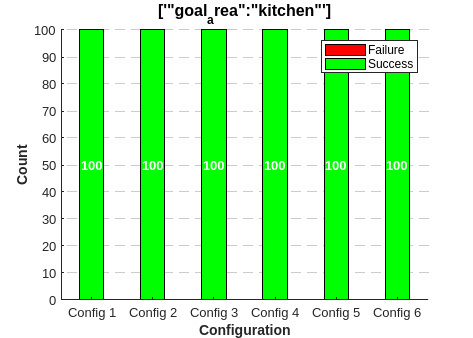

folderPath_kitchen = fullfile(go_to_area_function_folder,'kitchen');
column_kitchen = 'Function_arguments';
targetString_kitchen ="['{""goal_area"":""kitchen""}']";


plotSuccessFailure(folderPath_kitchen,column_kitchen,targetString_kitchen)

### "Office"

Taking a look at the result it is seen it often think it is "workshop" that the user is referring to. Looking at the input it often makes sense that it might end up confuse as a human probably also going to misunderstand the request. 

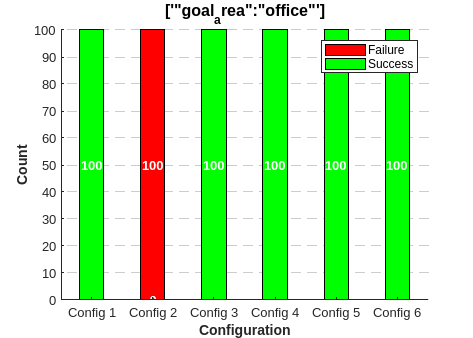

% Define the directory where the CSV files are stored
folderPath_office = fullfile(go_to_area_function_folder,'office');
column_office = 'Function_arguments';
targetString_office ="['{""goal_area"":""office""}']";


plotSuccessFailure(folderPath_office,column_office,targetString_office)


### "Bed Room"

text

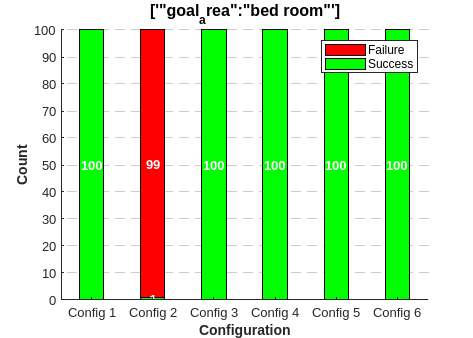

% Define the directory where the CSV files are stored
folderPath_bedroom = fullfile(go_to_area_function_folder,'bed room');
column_bedroom = 'Function_arguments';
targetString_bedroom ="['{""goal_area"":""bed room""}']";


plotSuccessFailure(folderPath_bedroom,column_bedroom,targetString_bedroom)

### "Living Room"

text

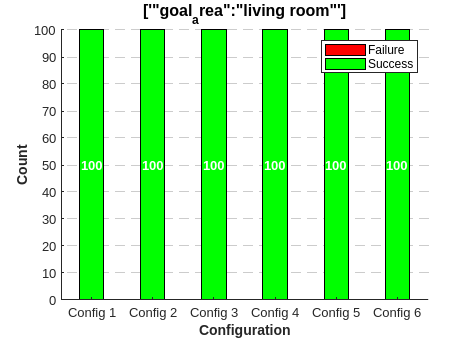

% Define the directory where the CSV files are stored
folderPath_living_room = fullfile(go_to_area_function_folder,'living room');
column_living_room = 'Function_arguments';
targetString_living_room ="['{""goal_area"":""living room""}']";


plotSuccessFailure(folderPath_living_room,column_living_room,targetString_living_room)

### "Dining Room"

text

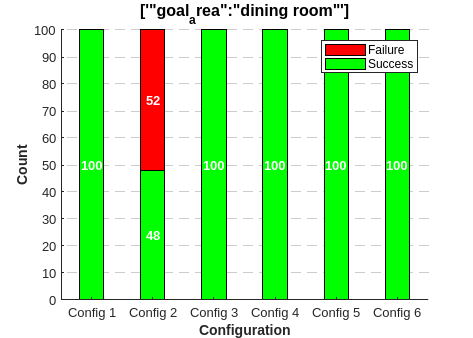

% Define the directory where the CSV files are stored
folderPath_dining_room = fullfile(go_to_area_function_folder,'dining room');
column_dining_room = 'Function_arguments';
targetString_dining_room ="['{""goal_area"":""dining room""}']";


plotSuccessFailure(folderPath_dining_room,column_dining_room,targetString_dining_room)

### "Workshop"

text

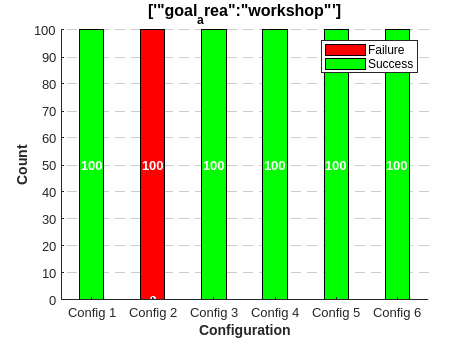

% Define the directory where the CSV files are stored
folderPath_workshop = fullfile(go_to_area_function_folder,'workshop');
column_workshop = 'Function_arguments';
targetString_workshop ="['{""goal_area"":""workshop""}']";


plotSuccessFailure(folderPath_workshop,column_workshop,targetString_workshop)

### "Garden"

text

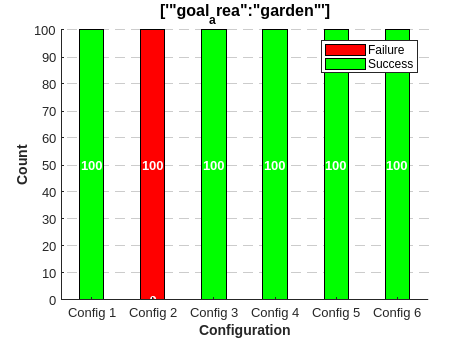

% Define the directory where the CSV files are stored
folderPath_garden = fullfile(go_to_area_function_folder,'garden');
column_garden = 'Function_arguments';
targetString_garden ="['{""goal_area"":""garden""}']";


plotSuccessFailure(folderPath_garden,column_garden,targetString_garden)

### "Garage"

text

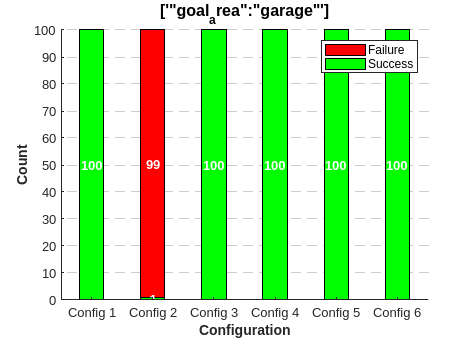

% Define the directory where the CSV files are stored
folderPath_garage = fullfile(go_to_area_function_folder,'garage');
column_garage = 'Function_arguments';
targetString_garage ="['{""goal_area"":""garage""}']";


plotSuccessFailure(folderPath_garage,column_garage,targetString_garage)

### "Home"

text

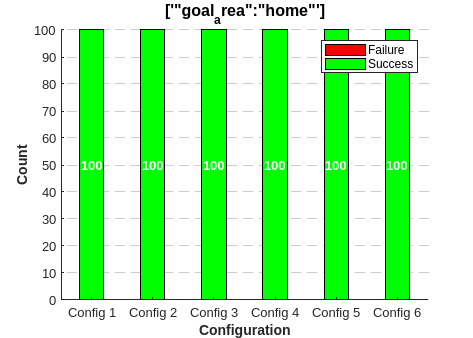

% Define the directory where the CSV files are stored
folderPath_home = fullfile(go_to_area_function_folder,'home');
column_home = 'Function_arguments';
targetString_home ="['{""goal_area"":""home""}']";


plotSuccessFailure(folderPath_home,column_home,targetString_home)

### "Fake Samples"

text

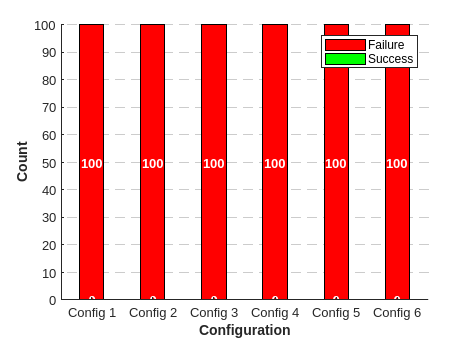

% Define the directory where the CSV files are stored
folderPath_fake_samples = fullfile(go_to_area_function_folder,'unknown');
column_location_fake_samples = 'Function_arguments';
targetString_location_fake_samples ="";


plotSuccessFailure(folderPath_fake_samples,column_location_fake_samples,targetString_location_fake_samples)

### All together in one

text

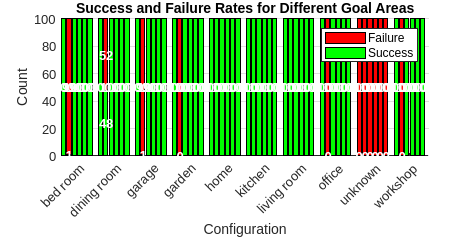

%targetStringsMap = containers.Map({'Kitchen', 'Office', 'Bedroom','Living_room','Dining_room','Workshop','Garden','Garage','Home','Fake_samples'},{targetString_kitchen,targetString_office, targetString_bedroom,targetString_living_room,targetString_dining_room,targetString_workshop, targetString_garden, targetString_garage, targetString_home,targetString_location_fake_samples});
% generateOverviewPlot(go_to_area_function_folder, 'Function_arguments', targetStringsMap);

goalAreas = {'["goal_area":"kitchen"]', '["goal_area":"workshop"]'};

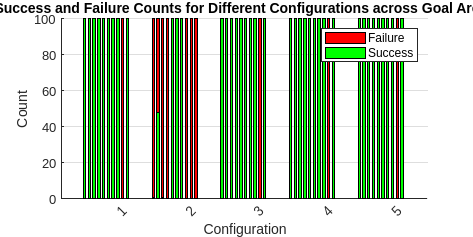

plotAllGoalAreas(go_to_area_function_folder);

plotConfigurations(go_to_area_function_folder);

## Locate_object function

Below are the result for running

locate_object_function_folder = '/home/rasmus/Desktop/Master/MasterThesisGit/final_tests/abstraction_tests/Test_results/GPT3/Sorted_for_matlab/Level00/locate_object';

### "Apple"

text

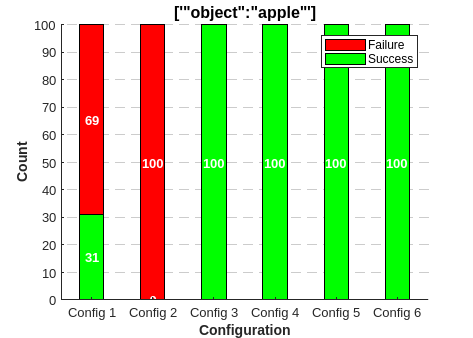

folderPath_apple = fullfile(locate_object_function_folder,'apple');
column_apple = 'Function_arguments';
targetString_apple ="['{""object"":""apple""}']";

plotSuccessFailure(folderPath_apple,column_apple,targetString_apple)

### "Banana"

text

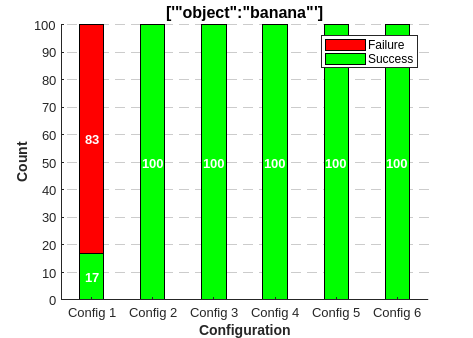

% Define the directory where the CSV files are stored
folderPath_banana = fullfile(locate_object_function_folder,'banana');
column_banana = 'Function_arguments';
targetString_banana ="['{""object"":""banana""}']";

plotSuccessFailure(folderPath_banana,column_banana,targetString_banana)

### "Bottle"

There exist no result for config1, hence commented out here

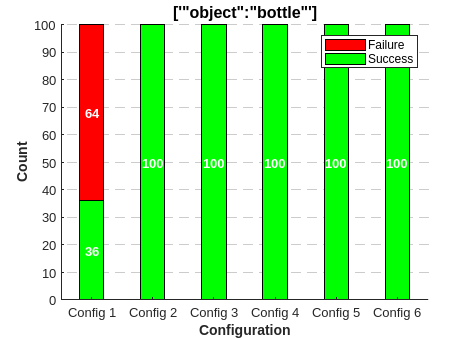

% Define the directory where the CSV files are stored
folderPath_bottle = fullfile(locate_object_function_folder,'bottle');
column_bottle = 'Function_arguments';
targetString_bottle ="['{""object"":""bottle""}']";

plotSuccessFailure(folderPath_bottle,column_bottle,targetString_bottle)

### "Bowl"

text

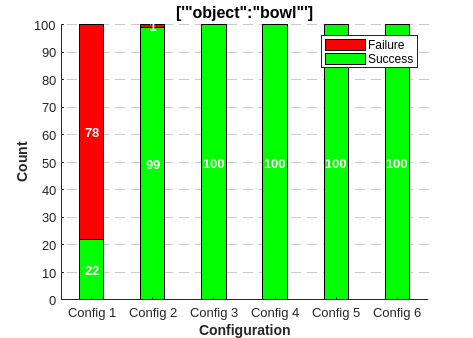

% Define the directory where the CSV files are stored
folderPath_bowl = fullfile(locate_object_function_folder,'bowl');
column_bowl = 'Function_arguments';
targetString_bowl ="['{""object"":""bowl""}']";

plotSuccessFailure(folderPath_bowl,column_bowl,targetString_bowl)

### "Cat"

text

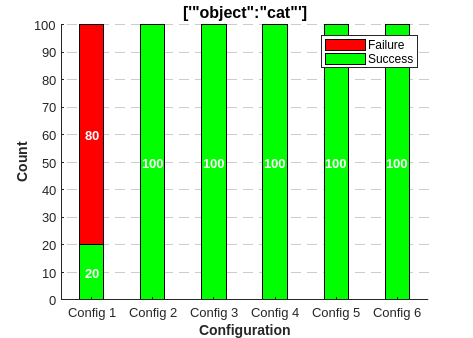

% Define the directory where the CSV files are stored
folderPath_cat = fullfile(locate_object_function_folder,'cat');
column_cat = 'Function_arguments';
targetString_cat ="['{""object"":""cat""}']";

plotSuccessFailure(folderPath_cat,column_cat,targetString_cat)

### "Cup"

text

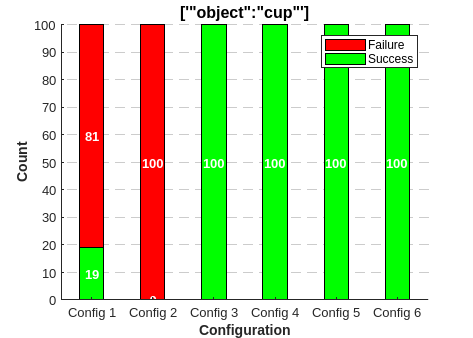

% Define the directory where the CSV files are stored
folderPath_cup = fullfile(locate_object_function_folder,'cup');
column_cup = 'Function_arguments';
targetString_cup ="['{""object"":""cup""}']";

plotSuccessFailure(folderPath_cup,column_cup,targetString_cup)

### "Dog"

text

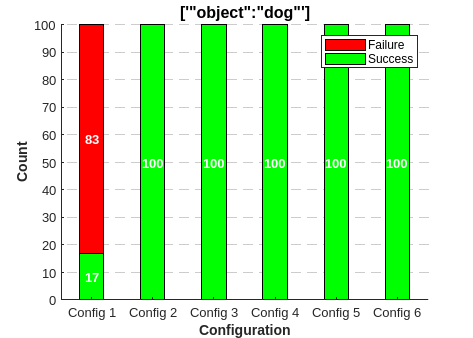

% Define the directory where the CSV files are stored
folderPath_dog = fullfile(locate_object_function_folder,'dog');
column_dog = 'Function_arguments';
targetString_dog ="['{""object"":""dog""}']";

plotSuccessFailure(folderPath_dog,column_dog,targetString_dog)

### "Laptop"

text

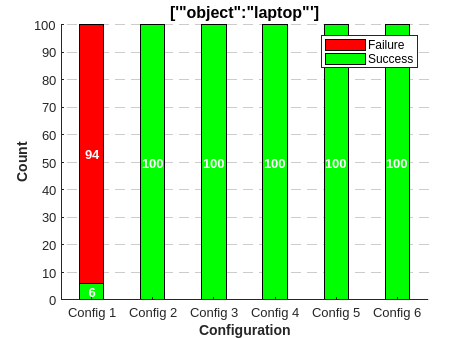

% Define the directory where the CSV files are stored
folderPath_laptop = fullfile(locate_object_function_folder,'laptop');
column_laptop = 'Function_arguments';
targetString_laptop ="['{""object"":""laptop""}']";

plotSuccessFailure(folderPath_laptop,column_laptop,targetString_laptop)

### "Person"

text

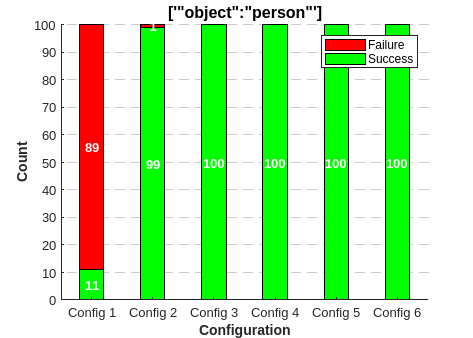

% Define the directory where the CSV files are stored
folderPath_person = fullfile(locate_object_function_folder,'person');
column_person = 'Function_arguments';
targetString_person ="['{""object"":""person""}']";

plotSuccessFailure(folderPath_person,column_person,targetString_person)

### "Refrigerator"

text

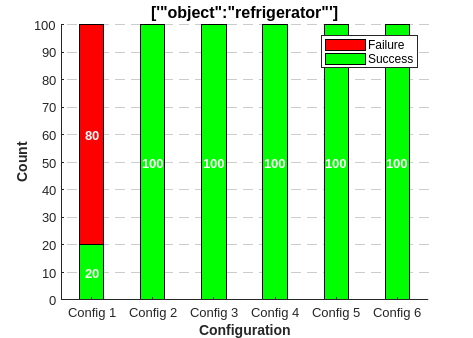

% Define the directory where the CSV files are stored
folderPath_refrigerator = fullfile(locate_object_function_folder,'refrigerator');
column_refrigerator = 'Function_arguments';
targetString_refrigerator ="['{""object"":""refrigerator""}']";

plotSuccessFailure(folderPath_refrigerator,column_refrigerator,targetString_refrigerator)

### "Teddy bear"

text

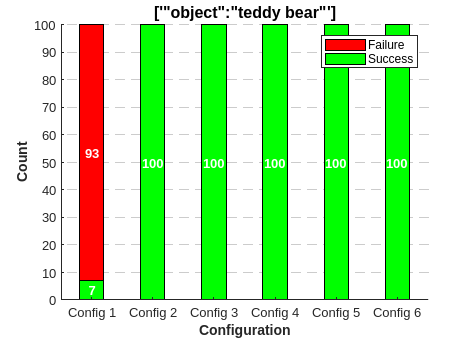

% Define the directory where the CSV files are stored
folderPath_teddy_bear = fullfile(locate_object_function_folder,'teddy bear');
column_teddy_bear = 'Function_arguments';
targetString_teddy_bear ="['{""object"":""teddy bear""}']";

plotSuccessFailure(folderPath_teddy_bear,column_teddy_bear,targetString_teddy_bear)

### "Fake Samples"

text

% Define the directory where the CSV files are stored
folderPath_fake_samples = fullfile(locate_object_function_folder,'unknown');
column_object_fake_samples = 'Function_arguments';
targetString_object_fake_samples ="";

plotSuccessFailure(folderPath_fake_samples,column_object_fake_samples,targetString_object_fake_samples)

Error using  .  (line 229)
Unrecognized table variable name 'Function_arguments'.

Error in Level00>countSuccessFailure (line 6)
    statusData = data.(column);

Error in 

### All together in one

text

% targetStringsMap = containers.Map({'Kitchen', 'Office', 'Bedroom','Living_room','Dining_room','Workshop','Garden','Garage','Home','Fake_samples'},{targetString_kitchen,targetString_office, targetString_bedroom,targetString_living_room,targetString_dining_room,targetString_workshop, targetString_garden, targetString_garage, targetString_home,targetString_location_fake_samples});
% generateOverviewPlot(go_to_area_function_folder, 'Function_arguments', targetStringsMap);

plotAllLocateObject(locate_object_function_folder);
%plotLocateConfigurations(locate_object_function_folder);

## Question/Answer function

Below are the result for running

## Old code might need

% % Load the CSV file
% file_name_1kitchen ='/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Prompt_config1/01kitchen_commands.csv';
% 
% % Preparing data
% column = 'Function_arguments';
% targetString = "['{""goal_area"":""Kitchen""}']";
% targetString2 = "['{""goal_area"":""Bed Room""}']";
% [successCount, failureCount] = countSuccessFailure(file_name_1kitchen, column, targetString);
% 
% fprintf('Success count: %d\n', successCount);
% fprintf('Failure count: %d\n', failureCount);
% 
% % Calculate the percentage of success and failure
% percentageSuccess = (successCount / (successCount + failureCount)) * 100;
% percentageFailure = (failureCount / (successCount + failureCount)) * 100;
% 
% % Define colors for the bars
% colorSuccess = [0.2, 0.7, 0.3]; % Green
% colorFailure = [0.9, 0.2, 0.1]; % Red
% 
% % Create a bar plot with failure bars stacked on top of success bars
% categories = {'Kitchen'};
% bar(1, [percentageSuccess, percentageFailure], 'stacked');
% 
% % Set colors for each segment of the bar
% colormap([colorSuccess; colorFailure]);
% 
% text(1, percentageSuccess/2, sprintf('%.2f%%', percentageSuccess), ...
%     'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'white');
% text(1, percentageSuccess + percentageFailure/2, sprintf('%.2f%%', percentageFailure), ...
%     'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'white');
% 
% % Set labels and title
% set(gca, 'XTickLabel', categories);
% xlabel('Outcome');
% ylabel('Success / Failure');
% title('Success rate');
% 
% % Set y-axis limits
% ylim([0 100]);
% 
% filename1 = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Prompt_config1/01kitchen_commands.csv';
% filename2 = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Prompt_config1/01bedroom_commands.csv';
% filename3 = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Prompt_config1/01kitchen_commands.csv';
% 
% % Call the function to get counts for each experiment
% [countSuccess1, countFailure1] = countSuccessFailure(filename1, column, targetString);
% [countSuccess2, countFailure2] = countSuccessFailure(filename2, column, targetString2);
% [countSuccess3, countFailure3] = countSuccessFailure(filename3, column, targetString);
% 
% % Define colors for the bars
% colorSuccess = [0 0 1]; % Blue for success
% colorFailure = [1 0 0]; % Red for failure
% 
% % Set the width of the bars here (between 0 and 1)
% barWidth = 0.4; % Smaller value for thinner bars
% 
% xPositions = 1:3;
% 
% % Create grouped bar graph
% fig = figure;
% b = bar(xPositions, [[countSuccess1 countFailure1]; [countSuccess2 countFailure2]; [countSuccess3 countFailure3]],barWidth, 'stacked');
% 
% % After plotting the success, plot failure on top to create stacked effect
% % The first bar object corresponds to success
% set(b(1), 'FaceColor', colorSuccess);
% % The second bar object corresponds to failure
% set(b(2), 'FaceColor', colorFailure);
% 
% % Add text labels for each success and failure value
% for i = 1:length(xPositions)
%     % Text for success count
%     successText = num2str(b(1).YData(i));
%     text(i, b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'white','FontWeight', 'bold');
% 
%     % Text for failure count, displayed above the success count
%     if b(2).YData(i) > 0
%         failureText = num2str(b(2).YData(i));
%         text(i, b(1).YData(i) + b(2).YData(i)/2, failureText, 'HorizontalAlignment', 'center', 'Color', 'white','FontWeight', 'bold');
%     end
% end
% 
% % Add legend
% legend({'Success', 'Failure'}, 'Location', 'NorthEast');
% 
% % Set labels and title
% xlabel('Configuration');
% ylabel('Count');
% title('Success and Failure Rates for Different Configurations');
% 
% % Set x-axis limits and ticks
% xlim([0.5, 3.5]);
% xticks(xPositions);
% xticklabels({'Config-1', 'Config-2', 'Config-3'});
% 
% % Show the figure
% %set(fig, 'Visible', 'on');
% % Define the directory where the CSV files are stored
% %folderPath_kitchen = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Test';